# Metarate example 

This script provides examples of how the functions in this repository can be used to:

- calculate rate measures using the proportional duration summation method

- conduct a scalographic analysis

- plot a scalogram and a difference of scalograms

The workflow used to conduct analyses for the paper "Parameters of unit-based measures of speech rate" is documented in `metarate_workflow.mlx`.

Two inputs are necessary:

- A table of utterance-based segmentations, with segmentation information described below. Here we use `metarate_segmentdata_example.mat`, which contains segmented utterances from a single speaker (F01) from the HPRC corpus and can be found in the `examples` subdirectory of this repository.

- A table of target variables, with duration and location information described below. Here we use `data_pb_example.mat`, which contains the durations of /p/ and /b/ segments from the speaker.

Add all sub-directories of the respository to the path:

addpath(genpath('.'));

#### Utterance segmentation

A unit-based segmentation of utterances is needed. 

load('metarate_segmentdata_example.mat','TR');

Each utterance is associated with arrays of unit labels, such as phones and words:

list_of_phones = TR.phones{1}

list_of_phones = 1×29 cell array
    {'sp'}    {'DH'}    {'AH0'}    {'B'}    {'ER1'}    {'CH'}    {'K'}    {'AH0'}    {'N'}    {'UW1'}    {'S'}    {'L'}    {'IH1'}    {'D'}    {'AA1'}    {'N'}    {'DH'}    {'IY0'}    {'S'}    {'M'}    {'UW1'}    {'DH'}    {'P'}    {'L'}    {'AE1'}    {'NG'}    {'K'}    {'S'}    {'sp'}


list_of_words = TR.words{1}

list_of_words = 1×10 cell array
    {'sp'}    {'THE'}    {'BIRCH'}    {'CANOE'}    {'SLID'}    {'ON'}    {'THE'}    {'SMOOTH'}    {'PLANKS'}    {'sp'}


The start and end times of each unit (here relative to the beginning of the recording) must be included as well, e.g.:

vector_of_phone_start_times = TR.phones_t0{1}

vector_of_phone_start_times =          0    0.2000    0.2499    0.2898    0.3596    0.4594    0.5293    0.5991    0.6290    0.6889    0.7288    0.8485    0.9084    0.9383    0.9782    1.0281    1.0580    1.0880    1.1179    1.2476    1.2975    1.4073    1.4372    1.5270    1.6068    1.6367    1.6667    1.7365    1.8762


vector_of_phone_end_times = TR.phones_t1{1}

vector_of_phone_end_times =     0.2000    0.2499    0.2898    0.3596    0.4594    0.5293    0.5991    0.6290    0.6889    0.7288    0.8485    0.9084    0.9383    0.9782    1.0281    1.0580    1.0880    1.1179    1.2476    1.2975    1.4073    1.4372    1.5270    1.6068    1.6367    1.6667    1.7365    1.8762    2.0762


In addition, maps between units at different levels must be included (but only if the rate measure unit is different from the target variable unit):

%the integer indices of words for each phone:
indices_of_words_byphone = TR.phones_word_ix{1}

indices_of_words_byphone =      1     2     2     3     3     3     4     4     4     4     5     5     5     5     6     6     7     7     8     8     8     8     9     9     9     9     9     9    10


%the integer indices of phones for each word:
indices_of_phones_byword = TR.words_phone_ix{1}

indices_of_phones_byword = 1×10 cell array
    {[1]}    {[2 3]}    {[4 5 6]}    {[7 8 9 10]}    {[11 12 13 14]}    {[15 16]}    {[17 18]}    {[19 20 21 22]}    {[23 24 25 26 27 28]}    {[29]}


#### Target variables

A table of target variables is needed.

load('data_pb_example.mat','D');

This table contains the duration of each phone, along with its start and end times, its midpoint, and its index (in the utterance):

info_target_phone = head(D(:,{'phone' 'dur' 't0' 't1' 'tmid' 'ix'}))

info_target_phone = 8×6 table
    phone      dur         t0         t1        tmid      ix
    _____    ________    _______    _______    _______    __

    {'B'}    0.069841     0.2898    0.35964    0.32472     4
    {'P'}    0.089796     1.4372      1.527     1.4821    23
    {'B'}    0.099773    0.26984    0.36961    0.31973     4
    {'P'}    0.089796     1.9161     2.0059      1.961    23
    {'B'}    0.079819    0.27982    0.35964    0.31973     4
    {'P'}    0.089796      1.976     2.0658     2.0209    24
    {'B'}    0.029932      1.058      1.088      1.073    18
    {'B'}    0.059864     1.1977     1.2576     1.2277    21


The table also contains information about the higher-level units that contain the phones:

info_word_contains_target_phone = head(D(:,{'word' 'word_t0' 'word_t1'}))

info_word_contains_target_phone = 8×3 table
         word         word_t0    word_t1
    ______________    _______    _______

    {'BIRCH'     }     0.2898    0.52925
    {'PLANKS'    }     1.4372     1.8762
    {'BIRCH'     }    0.26984    0.61905
    {'PLANKS'    }     1.9161      2.405
    {'BIRCH'     }    0.27982    0.59909
    {'PLANKS'    }      1.976     2.4549
    {'BLUE'      }      1.058     1.1977
    {'BACKGROUND'}     1.1977     1.6667


#### Proportional unit count timeseries

Use the function `metarate_calc_prop_durs` to calculate the timeseries of proportional counts for a given type of unit, and add these to the utterances table:

unit = 'words';
dt = 0.001;

for i=1:height(TR)

    %calculates frame time-points, proportional counts, and indices
    [frpnts,prop_dur,UIX] = metarate_calc_prop_durs(TR(i,:),unit,dt);

    %add the outputs to the table:
    TR.frt{i} = frpnts; 
    TR.([unit '_ufr_prop_dur']){i} = prop_dur;
    TR.([unit '_ufr_map']){i} = uint8(UIX);     %max of 256 different units in utterance
end

#### Scalographic analysis

% data selection strategy:
% bywindow, bytarget, beginanchored, endanchored
% use 'bytarget' to specify the across-window data selection strategy
datasel = 'bytarget'; 

% rate ratio:    
% 0: proper rate, 1: inverse rate, 2: both
invrate = 2; 

T = metarate_scalographic_analysis(TR,D,...
    'unit',unit,...
    'target_exclusion',true,...
    'data_selection',datasel,...
    'inverse_rate',invrate);

The output of `metarate_scalographic_analysis` is a table that contains various information about each analysis.

Included in the output is the partial correlation (rho), the p-value of the partial correlation, the rate measure used, the target variable name, the data selection strategy, the target exclusion parameter, the ratio expression (1 for inverse, 0 for proper), the number of tokens in the analysis, the number for which the rate measure was non-finite, the number for which an NaN value was observed, and the total number of valid tokens in the analysis:

head(T(:,{'rho' 'pval' 'rate_measure' 'target' 'scale' 'center'}))

ans = 8×6 table
       rho          pval       rate_measure     target      scale    center
    _________    __________    ____________    _________    _____    ______

     -0.14675    5.0024e-05     {'words'}      {'phone'}    0.05     -0.475
    -0.097479     0.0071601     {'words'}      {'phone'}    0.05      -0.45
     -0.11043     0.0022839     {'words'}      {'phone'}     0.1      -0.45
    -0.043524       0.23104     {'words'}      {'phone'}    0.05     -0.425
     -0.10058     0.0054855     {'words'}      {'phone'}     0.1     -0.425
     -0.14734    4.5024e-05     {'words'}      {'phone'}    0.15     -0.425
     -0.07758      0.032596     {'words'}      {'phone'}    0.05       -0.4
     -0.11449     0.0015704     {'words'}      {'phone'}     0.1       -0.4


head(T(:,{'data_selection' 'target_exclusion' 'inverse_rate'}))

ans = 8×3 table
    data_selection    target_exclusion    inverse_rate
    ______________    ________________    ____________

     {'bytarget'}          true                0      
     {'bytarget'}          true                0      
     {'bytarget'}          true                0      
     {'bytarget'}          true                0      
     {'bytarget'}          true                0      
     {'bytarget'}          true                0      
     {'bytarget'}          true                0      
     {'bytarget'}          true                0      


head(T(:,{'N_tokens' 'N_inf' 'N_nan' 'N_valid'}))

ans = 8×4 table
    N_tokens    N_inf    N_nan    N_valid
    ________    _____    _____    _______

      762         3        0        759  
      762         1        0        761  
      762         0        0        762  
      762         2        0        760  
      762         0        0        762  
      762         0        0        762  
      762         2        0        760  
      762         1        0        761  


#### Plotting scalograms

First prepare the scalographic information for plotting:

target_name = {'phone'};
rate_unit = {'words'}; 
inversion = 0;
exclusion = true;
datasel = {'bytarget'};

scvals = {{target_name rate_unit inversion exclusion datasel}};
G = prep_subsets(scvals);
G(1).subset

ans = struct with fields:
              target: {'phone'}
           rate_meas: {'words'}
        inverse_rate: 0
    target_exclusion: 1
      data_selection: {'bytarget'}


The function `prep_scalographs` generates a structure (with one element for each scalograph) with the centers (XX), scales (YY), and scalogram values (ZZ).

SC = prep_scalographs(T,G)

SC = struct with fields:
            XX: [951×1 double]
            YY: [191×1 double]
        varlab: '{\it{r}}^{\prime}'
            ZZ: [191×951 double]
     rho_range: [-0.2387 0.2545]
         clims: [-0.2397 0.2555]
          cmap: [5001×3 double]
    rho_levels: [0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000 1]
        panlab: ' \sim  word/s'
         ax_ix: 1


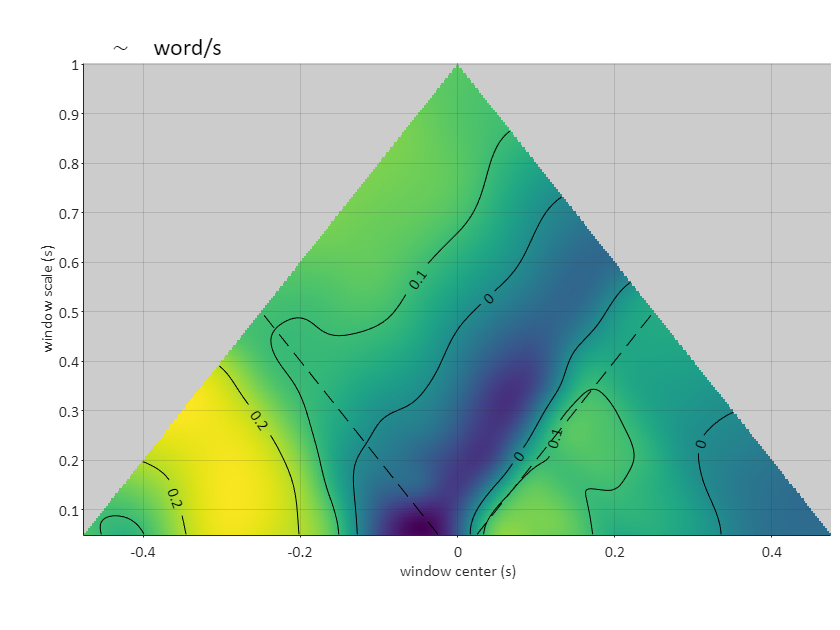

ax = stf([1 1],[0.10 0.15 0.01 0.10]); %makes a figure with one axis
handles = plot_scalographs(SC,ax);

#### Plotting a difference scalogram

First, let's conduct separate scalographic analyses on the /p/ and /b/ phones from our example dataset:

% make separate data tables
D_p = D(ismember(D.phone,{'P'}),:);
D_b = D(ismember(D.phone,{'B'}),:);

%conduct scalographic analyses
T_p = metarate_scalographic_analysis(TR,D_p,...
    'unit','words',...
    'target_exclusion',true,...
    'data_selection','bytarget',...
    'inverse_rate',0);

T_b = metarate_scalographic_analysis(TR,D_b,...
    'unit','words',...
    'target_exclusion',true,...
    'data_selection','bytarget',...
    'inverse_rate',0);

%rename target fields and combine:
T_p.target = repmat({'phone_p'},height(T_p),1);
T_b.target = repmat({'phone_b'},height(T_b),1);

T = [T_p; T_b];

Now let's prepare all three scalograms and plot:

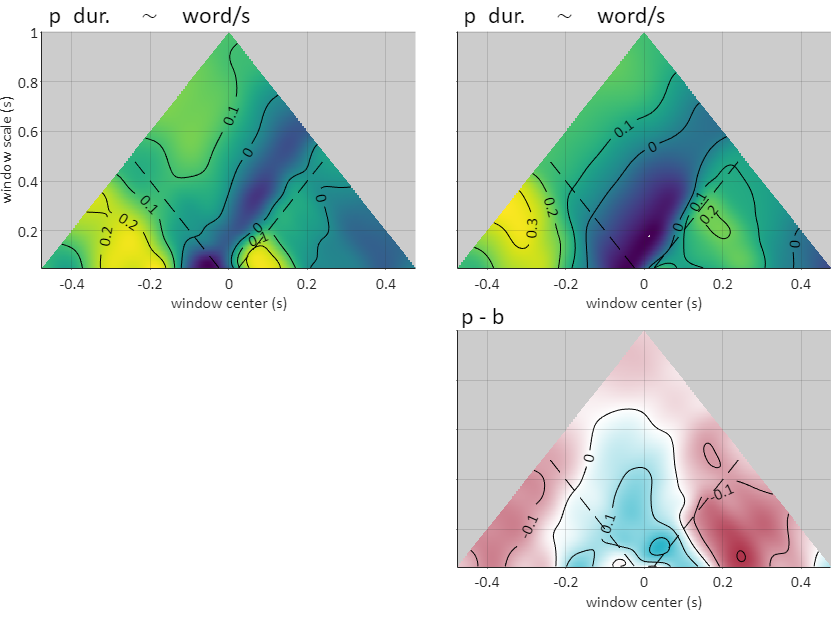

scvals{1} = {{'phone_p'} {'words'} 0 1 {'bytarget'}};
scvals{2} = {{'phone_b'} {'words'} 0 1 {'bytarget'}};
scvals{3} = {{'phone_p'} {'words'} 0 1 {'bytarget'};
             {'phone_b'} {'words'} 0 1 {'bytarget'}}; %note that we have two rows here
    
G = prep_subsets(scvals);
SC = prep_scalographs(T,G);

ax = stf([1 2; nan 3],[0.05 0.10 0.01 0.05],[0.05 0.10]); %creates a figure with some axes
handles = plot_scalographs(SC,ax);
handles.th(1).String = ['p dur. ' handles.th(1).String];
handles.th(2).String = ['p dur. ' handles.th(2).String];
handles.th(3).String = ['p - b'];